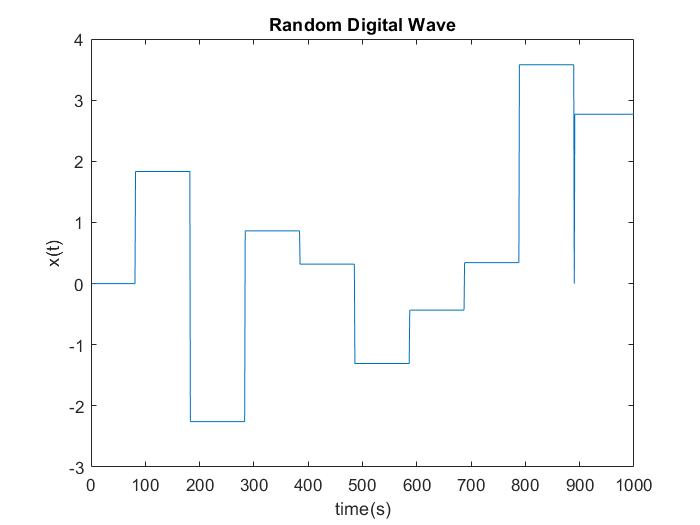

%Q1_Apart
length = 1;
frequency = 1000;
sigma = 1;
T = 0.1;
plot(digitalWave(length,frequency,sigma,T))
xlabel('time(s)')
ylabel('x(t)')
title('Random Digital Wave')

%Q1_B
length = 1;
frequency = 1000;
sigma = 1;
T = 0.1;
numberOfSignals = 1000;
[meanCorr,] = autocorrelation(length,frequency,sigma,T,numberOfSignals)

meanCorr =   939.7954  931.1072  922.4210  913.7394  905.0560  896.3679  887.6745  878.9804  870.2881  861.5996  852.9164  844.2322  835.5441  826.8578  818.1754  809.4883  800.8039  792.1207  783.4438  774.7658  766.0854  757.4074  748.7286  740.0496  731.3702  722.6904  714.0110  705.3305  696.6507  687.9693  679.2889  670.6071  661.9279  653.2455  644.5541  635.8606  627.1671  618.4705  609.7713  601.0749  592.3746  583.6750  574.9708  566.2687  557.5681  548.8715  540.1766  531.4842  522.7883  514.0950


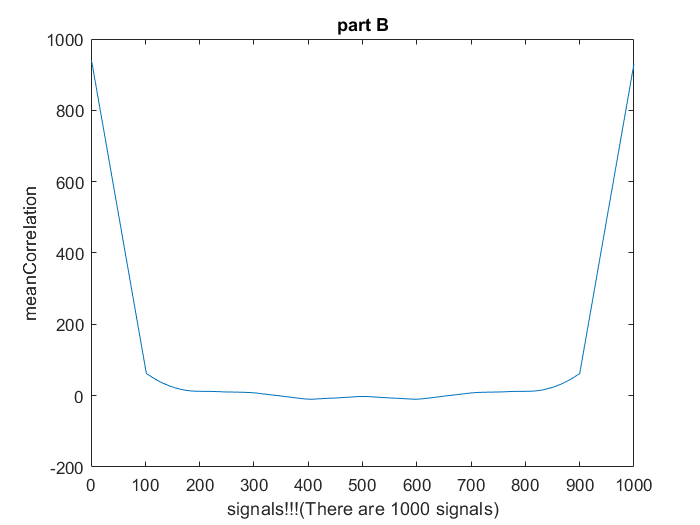

plot(meanCorr)
xlabel('signals!!!(There are 1000 signals)')
ylabel('meanCorrelation')
title('part B')

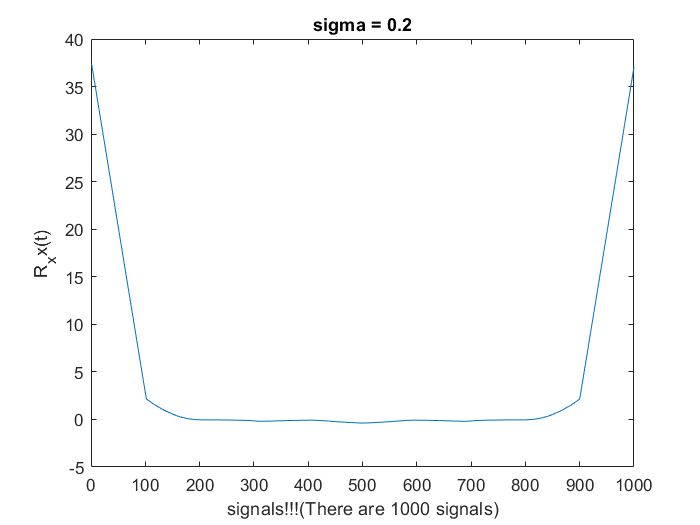

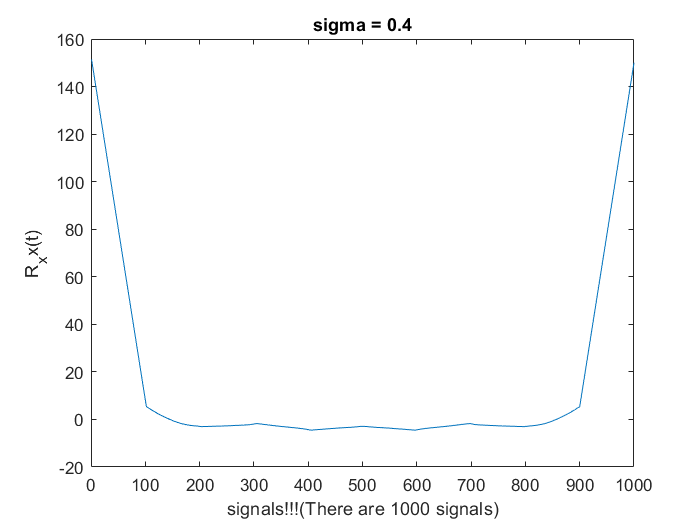

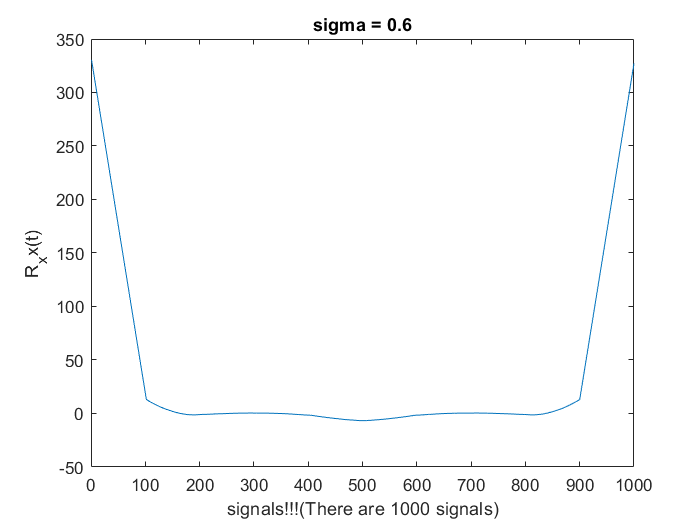

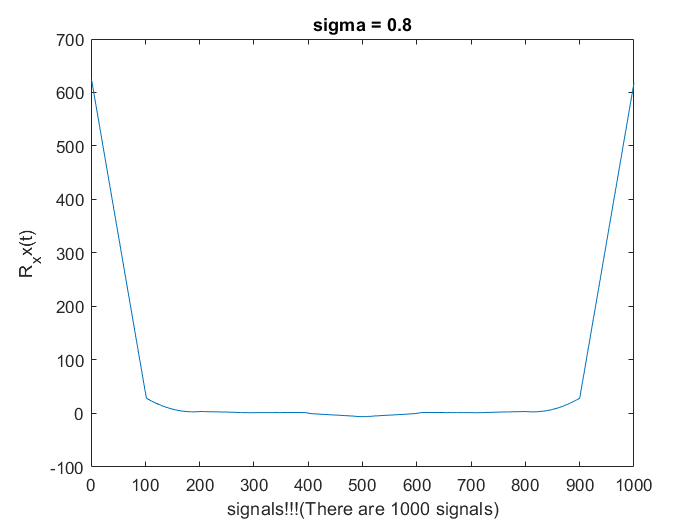

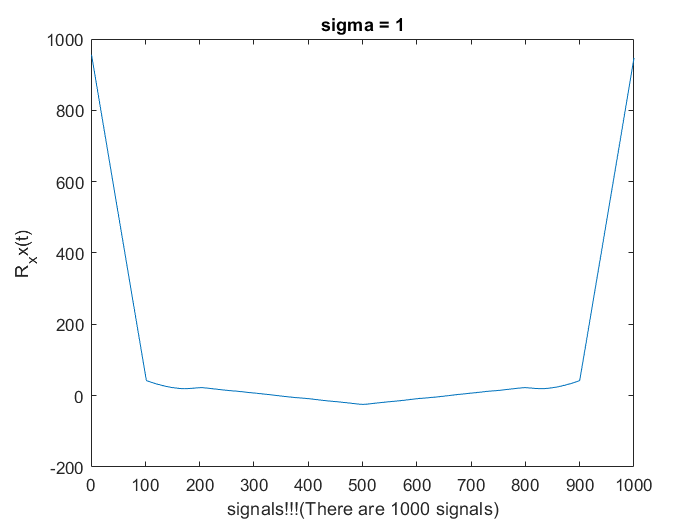

%Q1_C
% sweep from sigma = 0.1 to 1 Dont run this at all :)))) just read the
% results
length = 1;
frequency = 1000;
numberOfSignals = 1000;
T = 0.1;
for i = 1:5
    sigma = i/5;
    [meanCorr,] = autocorrelation(length,frequency,sigma,T,numberOfSignals);
    figure
    plot(meanCorr)
    xlabel('signals!!!(There are 1000 signals)')
    ylabel('R_xx(t)');
    title(['sigma = ',num2str(sigma)]);
end

meanCorr =   952.7322  943.6237  934.5179  925.4098  916.3041  907.1919  898.0741  888.9563  879.8331  870.7090  861.5835  852.4605  843.3354  834.2092  825.0804  815.9492  806.8091  797.6706  788.5345  779.3978  770.2623  761.1274  751.9909  742.8548  733.7221  724.5870  715.4541  706.3313  697.2106  688.0888  678.9705  669.8533  660.7364  651.6196  642.5025  633.3900  624.2747  615.1599  606.0455  596.9276  587.8110  578.6929  569.5704  560.4469  551.3264  542.2080  533.0836  523.9639  514.8421  505.7187


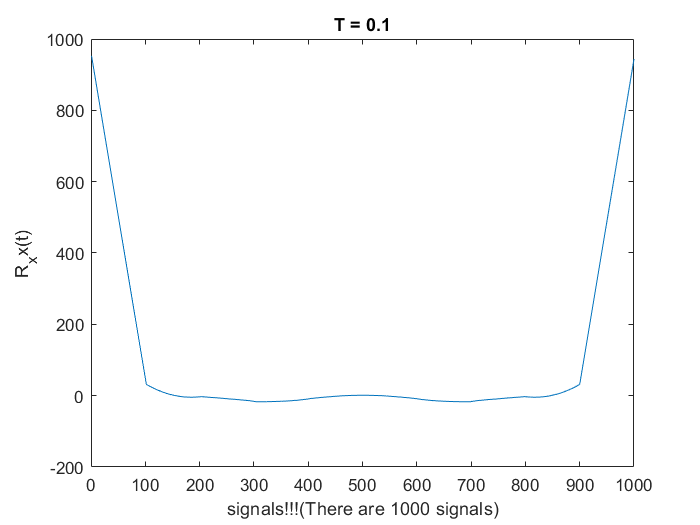

meanCorr =   884.4338  880.4376  876.4414  872.4441  868.4471  864.4445  860.4435  856.4435  852.4434  848.4435  844.4460  840.4485  836.4543  832.4601  828.4654  824.4734  820.4791  816.4847  812.4900  808.4942  804.5001  800.5029  796.5056  792.5100  788.5142  784.5185  780.5222  776.5243  772.5261  768.5277  764.5362  760.5443  756.5556  752.5646  748.5752  744.5858  740.5990  736.6114  732.6243  728.6370  724.6476  720.6583  716.6695  712.6784  708.6911  704.7064  700.7210  696.7334  692.7466  688.7622


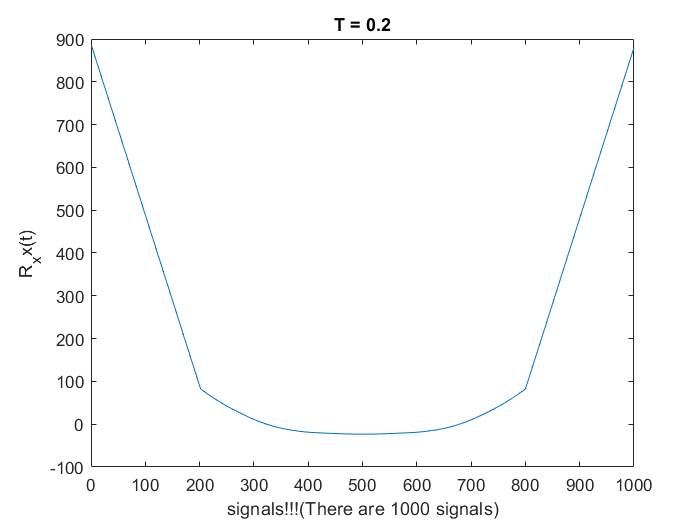

meanCorr =   788.5402  786.3139  784.0902  781.8674  779.6442  777.4209  775.1976  772.9722  770.7459  768.5206  766.2945  764.0669  761.8365  759.6053  757.3720  755.1391  752.9085  750.6785  748.4532  746.2280  744.0084  741.7915  739.5722  737.3514  735.1288  732.9042  730.6790  728.4534  726.2268  724.0002  721.7716  719.5466  717.3220  715.0968  712.8717  710.6487  708.4259  706.2002  703.9715  701.7432  699.5129  697.2828  695.0527  692.8229  690.5871  688.3557  686.1262  683.8961  681.6646  679.4335


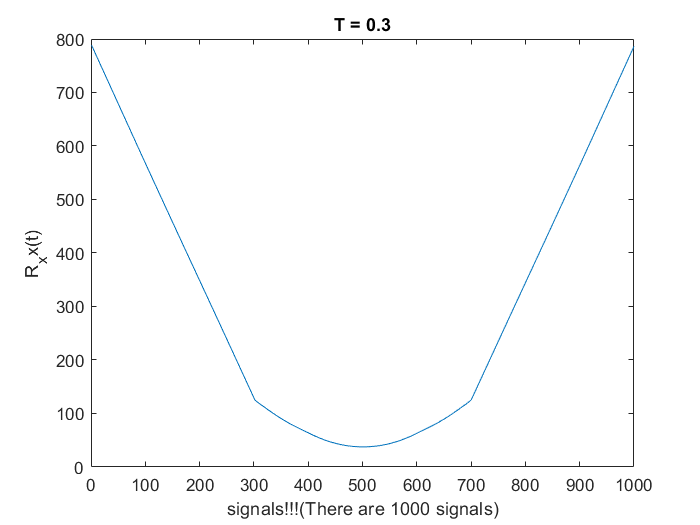

meanCorr =   784.5543  783.0579  781.5468  780.0351  778.5215  777.0087  775.4962  773.9837  772.4729  770.9611  769.4425  767.9238  766.4052  764.8873  763.3681  761.8490  760.3315  758.8125  757.2933  755.7758  754.2583  752.7394  751.2211  749.7014  748.1816  746.6624  745.1428  743.6213  742.1031  740.5849  739.0660  737.5468  736.0275  734.5088  732.9929  731.4710  729.9501  728.4328  726.9147  725.3967  723.8777  722.3587  720.8378  719.3163  717.7963  716.2779  714.7600  713.2421  711.7239  710.2043


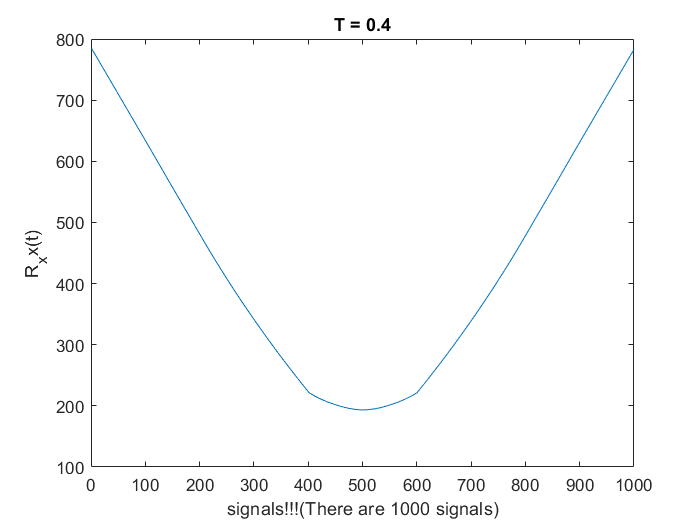

meanCorr =   741.9853  740.9863  739.9864  738.9902  737.9963  737.0057  736.0151  735.0245  734.0344  733.0448  732.0589  731.0779  730.0975  729.1172  728.1369  727.1591  726.1832  725.2078  724.2354  723.2652  722.2973  721.3295  720.3616  719.4029  718.4441  717.4890  716.5339  715.5793  714.6266  713.6751  712.7256  711.7763  710.8270  709.8826  708.9382  707.9945  707.0517  706.1089  705.1685  704.2298  703.2915  702.3533  701.4151  700.4868  699.5606  698.6348  697.7114  696.7918  695.8738  694.9559


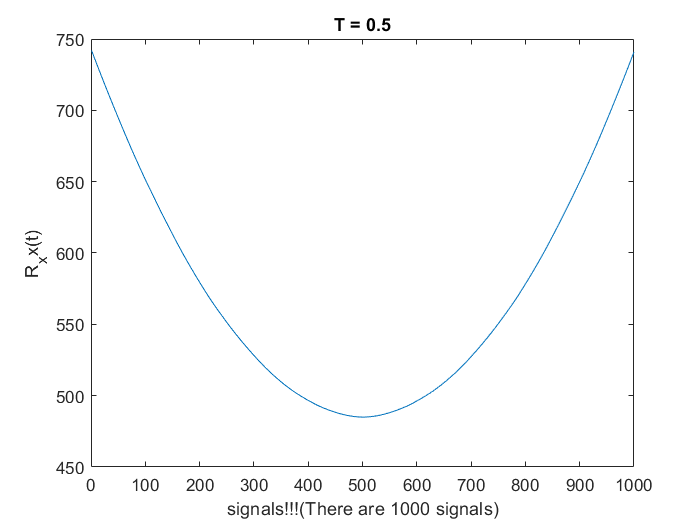

for i = 1:5
    T = i/10;
    figure
    [meanCorr,] = autocorrelation(length,frequency,sigma,T,numberOfSignals)
    figure
    plot(meanCorr)
    xlabel('signals!!!(There are 1000 signals)')
    ylabel('R_xx(t)');
    title(['T = ',num2str(i/10)]);
end

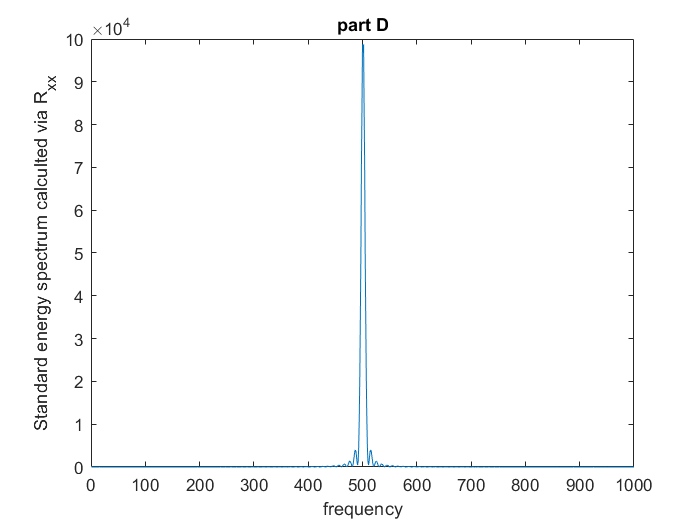

%Q1_D
length = 1;
frequency = 1000;
numberOfSignals = 1000;
T = 0.1;
sigma = 1;
[meanCorr,allsignals,correlations] = autocorrelation(length,frequency,sigma,T,numberOfSignals);
energy_viaRxx = abs(sdfViaCorrSignal(meanCorr));
plot(energy_viaRxx)
xlabel('frequency')
ylabel('Standard energy spectrum calculted via R_x_x')
title('part D')

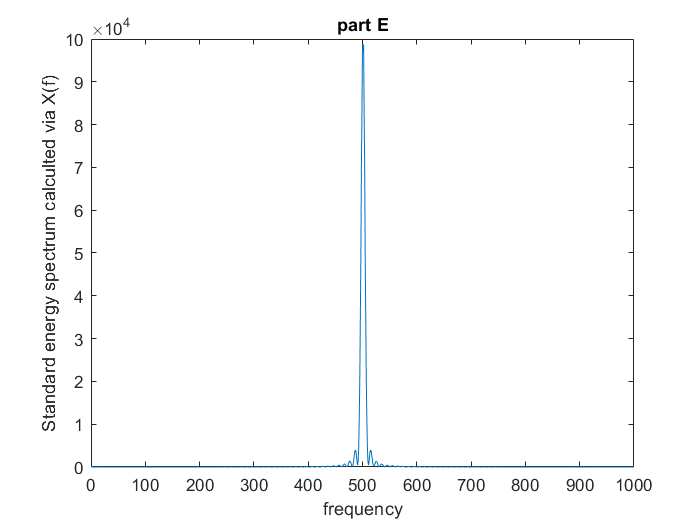

%Q1_E
% [meanCorr,allsignals,correlations] = autocorrelation(length,frequency,sigma,T,numberOfSignals);
energy = zeros(size(allsignals,1),size(allsignals,2));
for i=1:size(allsignals,1)
    extractedSignal = allsignals(i,:);
    fourierTrans = fftshift(fft(extractedSignal,size(extractedSignal,2)));
    energy(i,:) = fourierTrans.*conj(fourierTrans);
end
Energy_fourierTrans = mean(energy);
figure
plot(abs(Energy_fourierTrans));
xlabel('frequency')
ylabel('Standard energy spectrum calculted via X(f)')
title('part E')

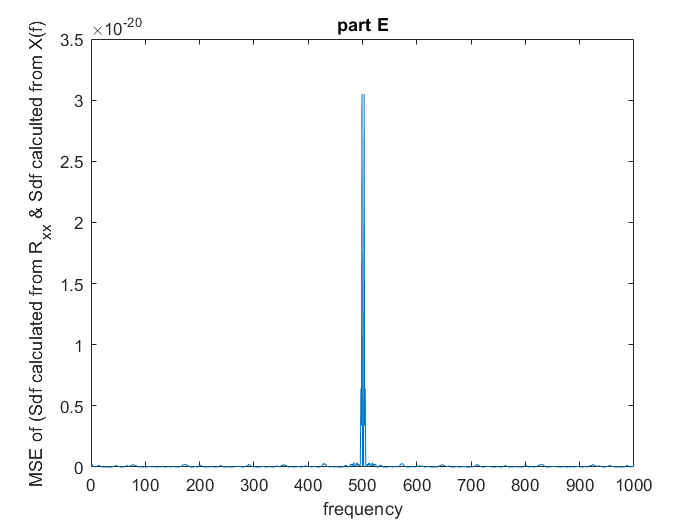

MSE = abs(energy_viaRxx - Energy_fourierTrans).^2;
MSE_mean = mean(MSE);
plot(MSE)
xlabel('frequency')
ylabel('MSE of (Sdf calculated from R_x_x & Sdf calculted from X(f)')
title('part E')

%Q1_F
length = 1;
frequency = 1000;
T = 0.1;
sigma = 1;
numberOfSignals = 1000;

eachSignalSize = length*frequency;  
allSignals = zeros(numberOfSignals,eachSignalSize); % we can change it by fixing of the outputSize!
for i = 1:numberOfSignals
    allSignals(i,:) = digitalWave(length,frequency,sigma,T);
end

sinDomain =  0 : 1/frequency : (size(allSignals,2)-1)/frequency; % syncing both sampling frequency & signalDomainNumber
sinus = sin(2*pi*200*sinDomain);
out = dotDigitalWave(sinus,allSignals);

numberOfSignals = 1000

eachSignalSize = 1000

out =   483.8766  148.1763 -384.0592 -380.4395  143.8370  461.0883  141.1313 -365.6199 -362.0014  136.7957  438.3016  134.0896 -347.1795 -343.5578  129.7465  415.4867  127.0384 -328.7152 -325.0926  122.6920  392.6590  119.9846 -310.2491 -306.6262  115.6445  369.8479  112.9341 -291.7985 -288.1755  108.5987  347.0390  105.8832 -273.3424 -269.7155  101.5478  324.2184   98.8302 -254.8782 -251.2482   94.4905  301.3862   91.7763 -236.4054 -232.7797   87.4377  278.5681   84.7268 -217.9520 -214.3300   80.3897


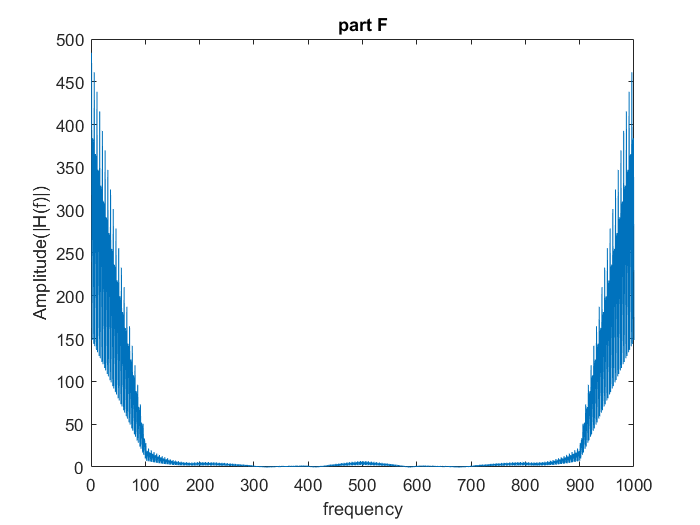

figure
plot(abs(out))
xlabel('frequency')
ylabel('Amplitude(|H(f)|)')
title('part F')

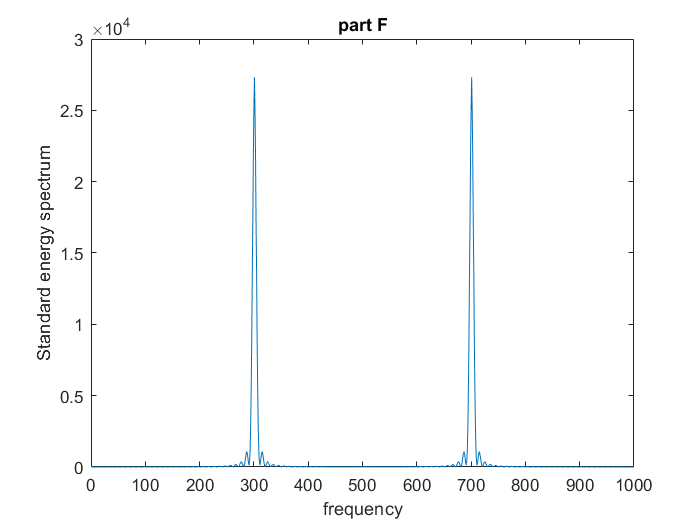

figure
plot(abs(sdfViaCorrSignal(out)))
xlabel('frequency')
ylabel('Standard energy spectrum')
title('part F')

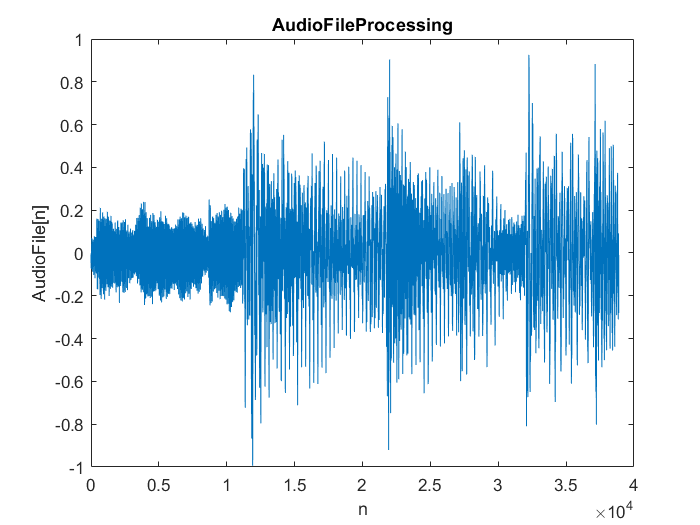

%Q2_a
[audioData,fs] =  audioread('clip.wav');
plot(audioData);
xlabel('n');
ylabel('AudioFile[n]');
title('AudioFileProcessing');

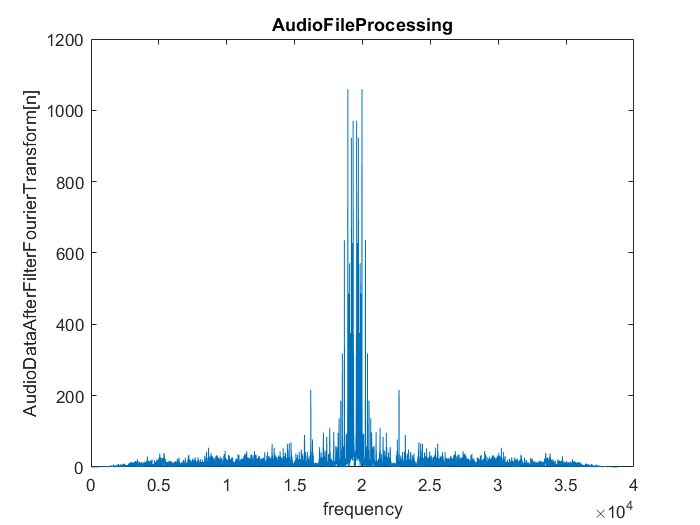

[audioDataSdf,audioDataFourierTransform] = sdf(transpose(audioData));
figure
plot(abs(audioDataFourierTransform))
xlabel('frequency');
ylabel('AudioDataAfterFilterFourierTransform[n]');
title('AudioFileProcessing');

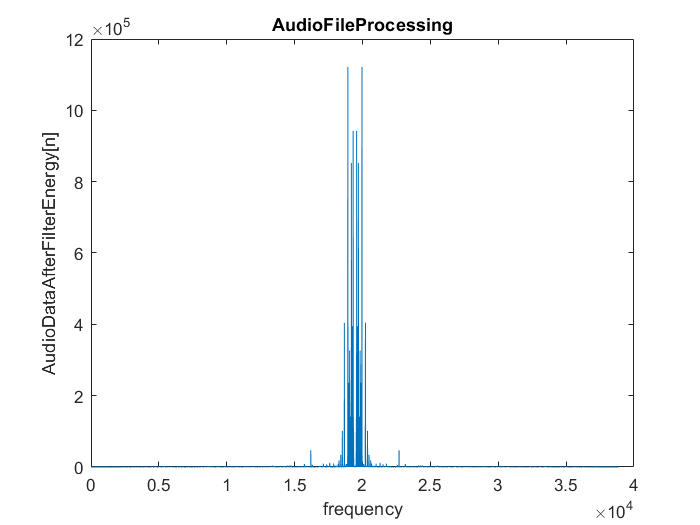

figure
plot(abs(audioDataSdf))
xlabel('frequency');
ylabel('AudioDataAfterFilterEnergy[n]');
title('AudioFileProcessing');

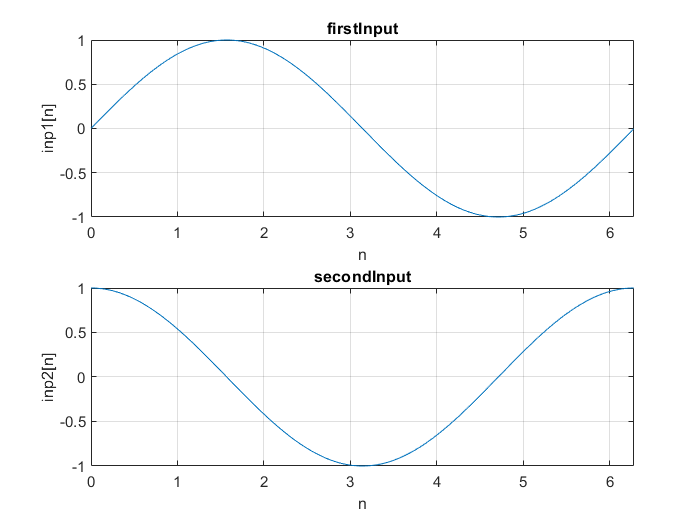

%Q2_b

% first verifying linearinty of the channel
domain = 0:0.01:2*pi;
inp1 = sin(domain);
inp2 = cos(domain);
totSignal = inp1+inp2;

out1 = Channel(inp1);
out2 = Channel(inp2);
totOut = Channel(totSignal);

figure
subplot(2,1,1)
plot(domain,inp1)
xlabel('n')
ylabel('inp1[n]')
title('firstInput')
xlim([0 2*pi])
grid on
subplot(2,1,2)
plot(domain,inp2)
xlabel('n')
title('secondInput')
ylabel('inp2[n]')
xlim([0 2*pi])
grid on

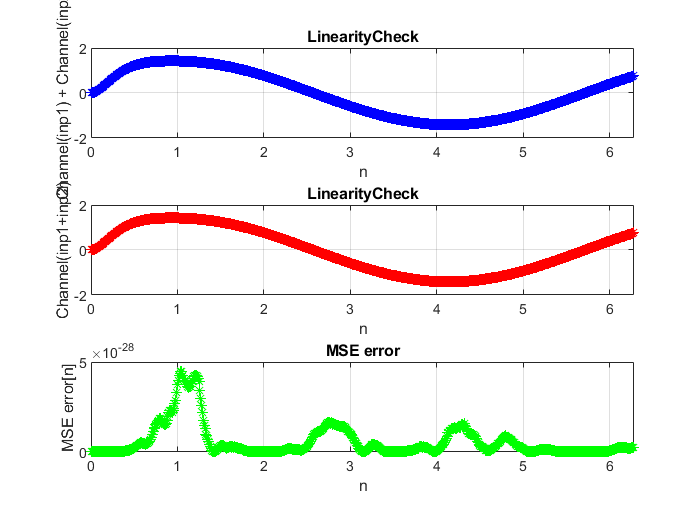

figure
subplot(3,1,1)
plot(domain,out1+out2,'b*')
xlabel('n')
ylabel('Channel(inp1) + Channel(inp2)')
title('LinearityCheck')
grid on
xlim([0 2*pi])
subplot(3,1,2)
plot(domain,totOut,'r*')
title('LinearityCheck')
xlabel('n')
ylabel('Channel(inp1+inp2)')
xlim([0 2*pi])
grid on
subplot(3,1,3)
MSE_linearity = abs(totOut-(out1+out2)).^2;
plot(domain,MSE_linearity,'g*')
xlabel('n')
ylabel('MSE error[n]')
title('MSE error')
xlim([0 2*pi])
grid on

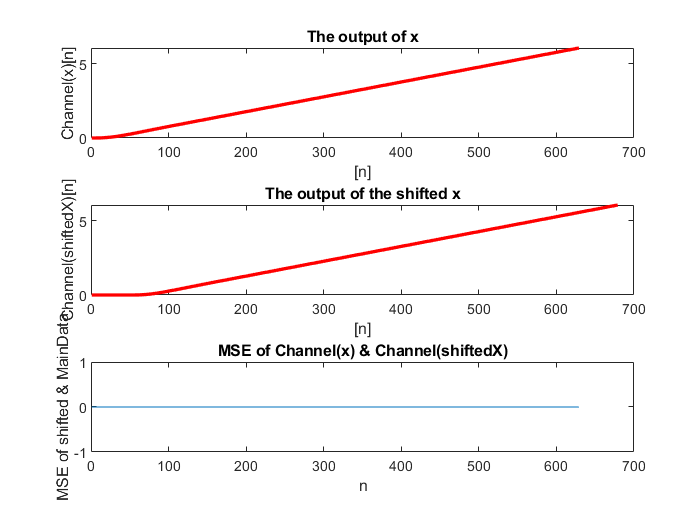

% second verifying timeVariant Check
shiftValue = 50;
x = 0:0.01:2*pi;
xShifted = [zeros(1,shiftValue) x];
y = Channel(x);
yShifted = Channel(xShifted);
figure
subplot(3,1,1)
plot(y,'r','linewidth',2)
title('The output of x')
ylabel('Channel(x)[n]')
xlabel('[n]')
subplot(3,1,2)
plot(yShifted,'r','linewidth',2)
title('The output of the shifted x')
xlabel('[n]')
ylabel('Channel(shiftedX)[n]')
MSE_timeInvariant = abs(yShifted(shiftValue + 1:end)-y).^2;
subplot(3,1,3)
plot(MSE_timeInvariant)
title('MSE of Channel(x) & Channel(shiftedX)')
xlabel('n')
ylabel('MSE of shifted & MainData')

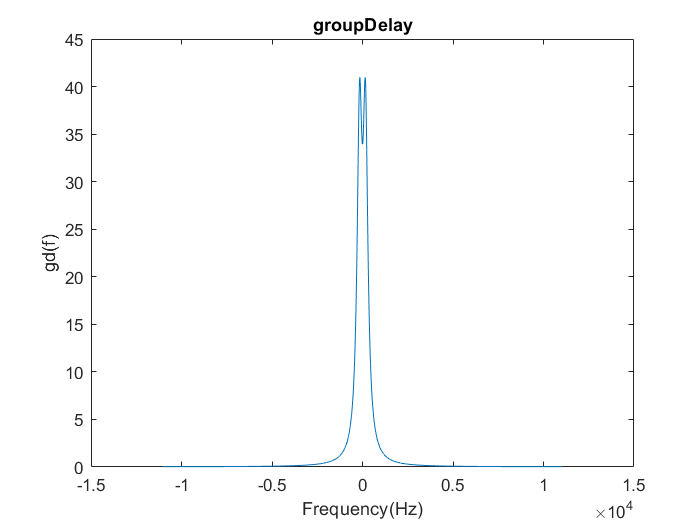

%Q2_c groupDelay & phaseDelay! 
% giving System delta input with the size of given clip.wmv
delta = [1 zeros(1,size(transpose(audioData),2)-1)];
h = Channel(delta);
n = 0:size(h,2)-1;
% using duality in the time & frequency Domain.
% derrivation in frequency == multipication in time domain
groupDelay = real(fourierDiscreteStandardTransform(n.*h)./fourierDiscreteStandardTransform(h))/2*pi;

%syncing input among -pi til pi.
frequency = 22050; % Hz
f = (0:size(groupDelay,2)-1)*(frequency)/(size(groupDelay,2)-1) - frequency/2;
figure
plot(f,groupDelay)
xlabel('Frequency(Hz)')
ylabel('gd(f)')
title('groupDelay')

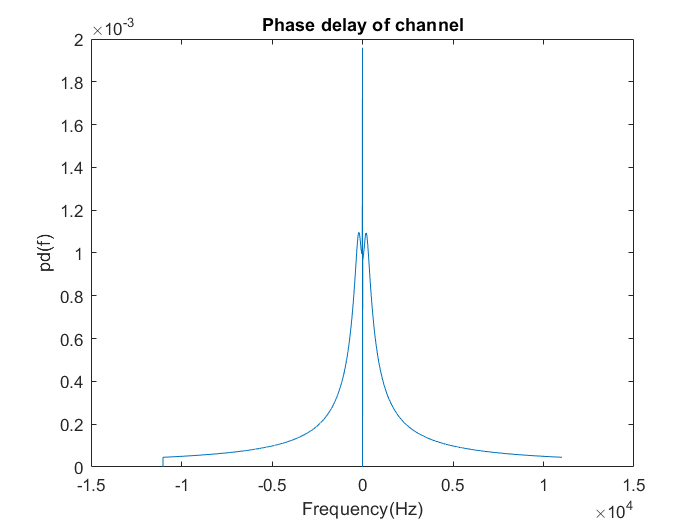

H = fourierDiscreteStandardTransform(h);
phase_delay = -angle(H)./(2*pi*f);
figure
plot(f,phase_delay)
xlabel('Frequency(Hz)')
ylabel('pd(f)')
title('Phase delay of channel')

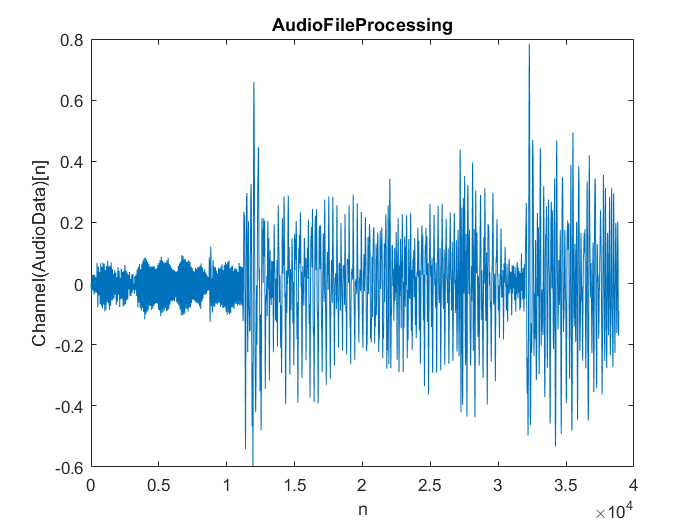

%Q2_d
audioChannelOutput = Channel(audioData);
figure
plot(audioChannelOutput);
xlabel('n');
ylabel('Channel(AudioData)[n]')
title('AudioFileProcessing')

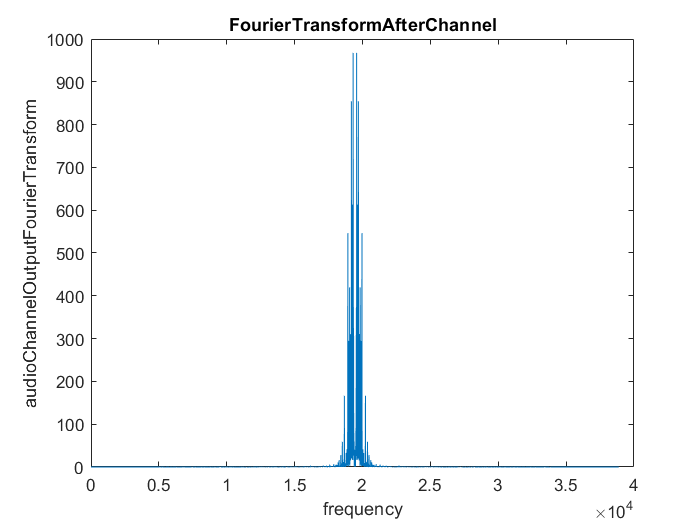

[audioChannelOutputSdf,audioChannelOutputFourierTransform] = sdf(transpose(audioChannelOutput));
figure
plot(abs(audioChannelOutputFourierTransform))
xlabel('frequency')
ylabel('audioChannelOutputFourierTransform')
title('FourierTransformAfterChannel')

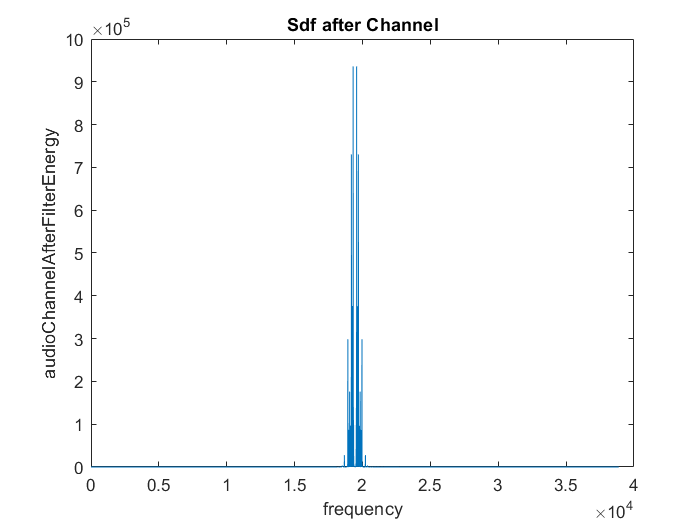

figure
plot(abs(audioChannelOutputSdf))
xlabel('frequency')
ylabel('audioChannelAfterFilterEnergy')
title('Sdf after Channel')

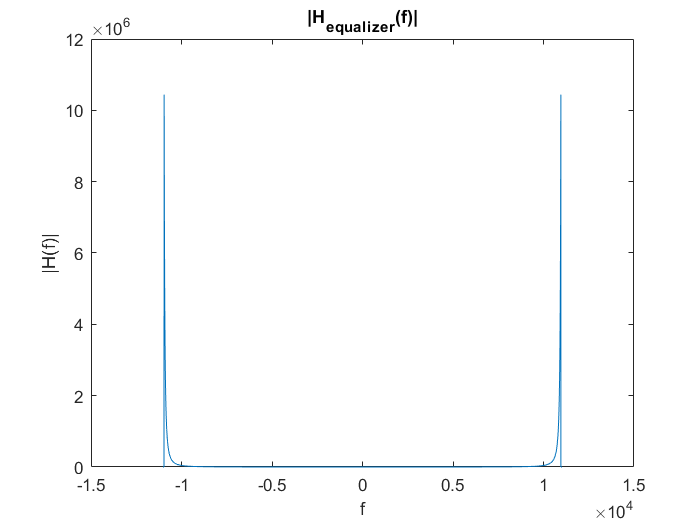

%Q2_e
% use band pass filter for those who are not too little.
threshHoldValue = 0.0000001;
gonnaRemoveIndexes = find(abs(H(floor(size(H,2)/2):end)) < threshHoldValue*max(abs(H)));
% remove from the first one.
BoundeStop = gonnaRemoveIndexes(1);
% Equalizer Setting.
Equalizer = zeros(1,size(H,2));
Pass_band = floor(size(H,2)/2)- BoundeStop+1 : floor(size(H,2)/2)+ BoundeStop+1;
Equalizer(Pass_band) = H(Pass_band).^-1;
plot(f,abs(Equalizer))
xlabel('f')
ylabel('|H(f)|')
title('|H_e_q_u_a_l_i_z_e_r(f)|')

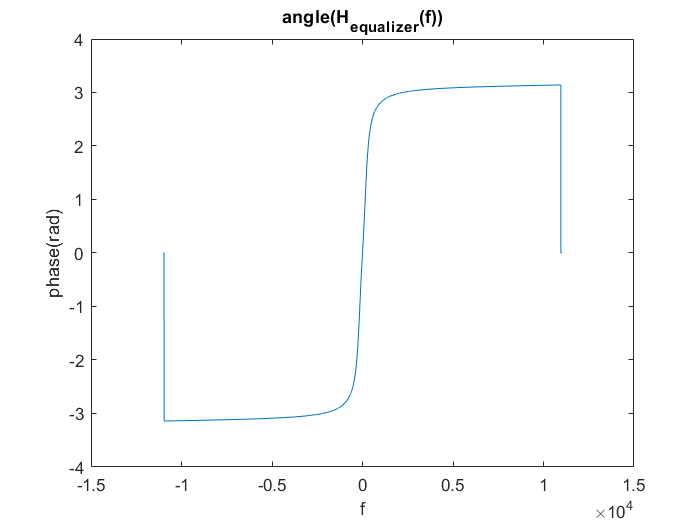

figure
plot(f,angle(Equalizer))
xlabel('f')
ylabel('phase(rad)')
title('angle(H_e_q_u_a_l_i_z_e_r(f))')

% checking the accurately of Equalizer
[audioData,fs] =  audioread('clip.wav');
audioDataTransform = fourierDiscreteStandardTransform(transpose(audioData));
audioChannelOutput = Channel(audioData);
afterEqualizer = fourierDiscreteStandardTransform(transpose(audioChannelOutput)).*Equalizer;
MSE = abs((afterEqualizer - audioDataTransform).^2)

MSE = 	1.0e+11 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


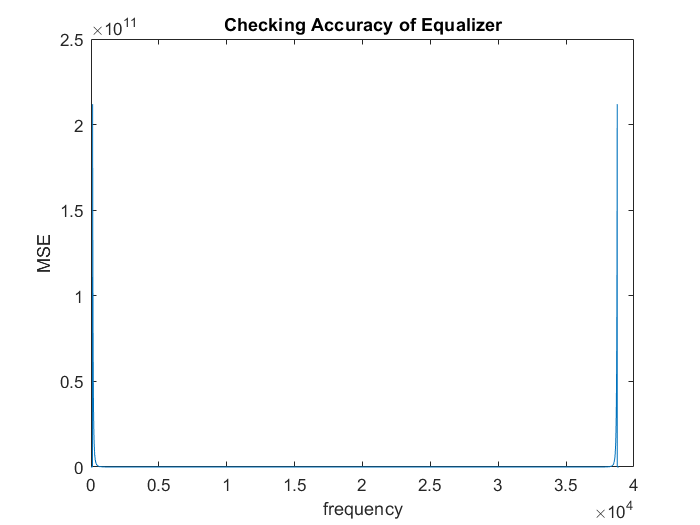

plot(MSE)
xlabel('frequency')
ylabel('MSE')
title('Checking Accuracy of Equalizer')

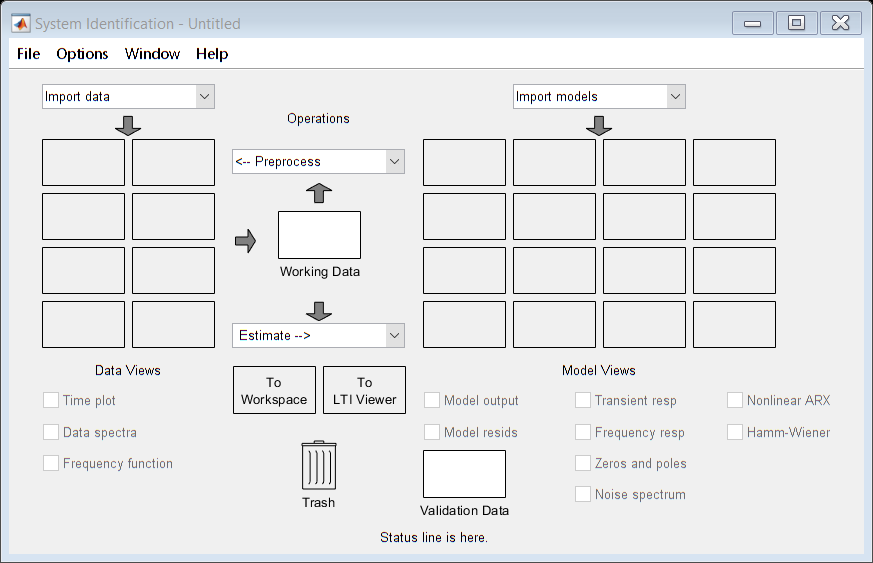

%Q2_f
% input output for Equalizer
% I told all the steps done this section in the report file.
systemIdentification

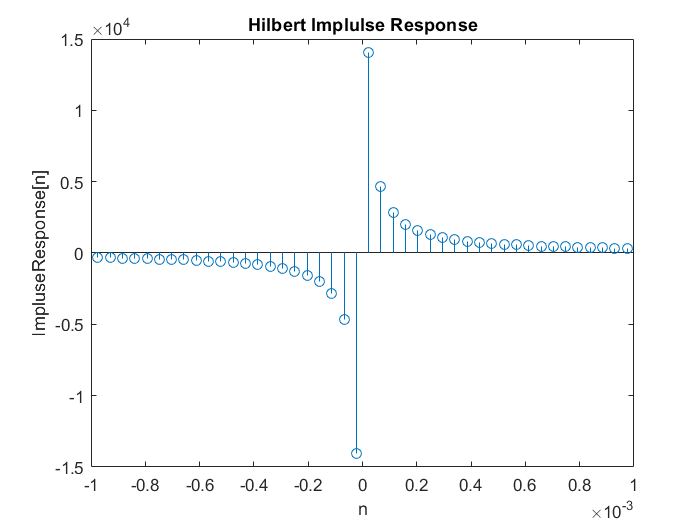

%Q3_a,Q3_b
frequency = 22050;
length = 1000; % youConsider.
[hilbertSignal,zeroIndex,domain] = hilbert(length,frequency);
% removing Zero values in order to enhance the curve.
% contact Me!
stem(domain,hilbertSignal);
xlim([-0.001 0.001])
xlabel('n')
title('Hilbert Implulse Response')
ylabel('ImpluseResponse[n]')

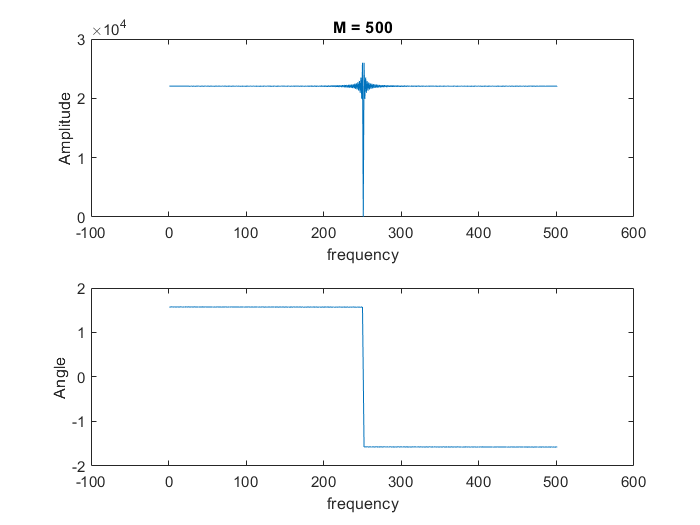

%Q3_c
M = 500;
numberOfDatas = M;
cutDot = floor(numberOfDatas/2);
afterFilter = zeros(1,2*cutDot+1);
afterFilter(1:end) = hilbertSignal(1,zeroIndex-cutDot:zeroIndex+cutDot);
myDomain = domain(zeroIndex-cutDot:zeroIndex + cutDot);
shiftSize = floor(M/2) + 1;
shiftedHilbert = circshift(afterFilter,shiftSize);
shiftedDomain = myDomain + shiftSize/frequency;
% critical condition happened Data Around
hilbertTransform = fourierDiscreteStandardTransform(shiftedHilbert);
w = (0:size(shiftedHilbert,2)-1)*2*pi/(size(shiftedHilbert,2)-1) - pi;
hilbertTransform = hilbertTransform.*exp(1i*-0.5*w);
magnitude = abs(hilbertTransform);
angle1 = angle(hilbertTransform);
figure
subplot(2,1,1)
plot(magnitude)
xlabel('frequency');
ylabel('Amplitude');
xlim([-100 600])
title(['M = ',num2str(M)]);
subplot(2,1,2)
plot(angle1)
xlabel('frequency')
xlim([-100 600])
ylabel('Angle')

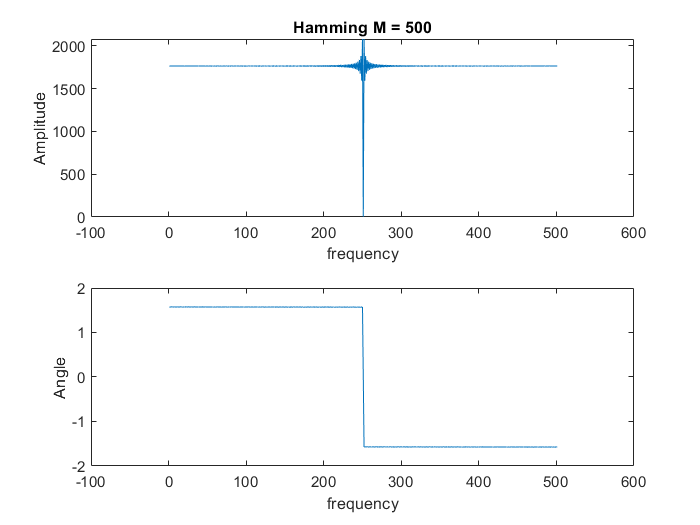

%Q3_d
M = 500;
numberOfDatas = M;
cutDot = floor(numberOfDatas/2);
afterFilter = zeros(1,2*cutDot+1);
afterFilter(1:end) = hilbertSignal(1,zeroIndex-cutDot:zeroIndex+cutDot);
myDomain = domain(zeroIndex-cutDot:zeroIndex + cutDot);
shiftSize = floor(M/2) + 1;
shiftedHilbert = circshift(afterFilter,shiftSize);
shiftedDomain = myDomain + shiftSize/frequency;
afterHammingFilter = shiftedHilbert.*hamming(domain(zeroIndex-cutDot:zeroIndex+cutDot),M,shiftSize);
myDomain = domain(zeroIndex-cutDot:zeroIndex + cutDot);
% shiftedHilbert = zeros(1,size(afterRect,2));
shiftedHilbert = myDomain + M/2;
figure

afterFilterTransform = fourierDiscreteStandardTransform(afterHammingFilter);
w = (0:size(afterFilterTransform,2)-1)*2*pi/(size(afterFilterTransform,2)-1) - pi;
afterFilterTransform = afterFilterTransform.*exp(1i*-0.5*w);

figure
subplot(2,1,1)
plot(abs(afterFilterTransform))
xlabel('frequency');
ylabel('Amplitude');
xlim([-100 600])
title(['Hamming M = ',num2str(M)]);
subplot(2,1,2)
plot(angle(afterFilterTransform))
xlabel('frequency');
xlim([-100 600])
ylabel('Angle');

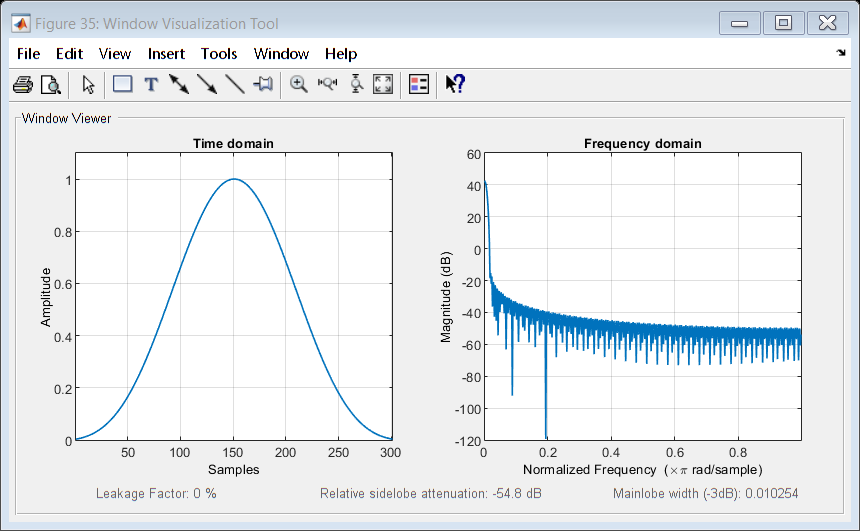

% Last 
%% Bonus Part (Kaiser Window)
M = 300;
numberOfDatas = M;
cutDot = floor(numberOfDatas/2);
afterFilter = zeros(1,2*cutDot+1);
afterFilter(1:end) = hilbertSignal(1,zeroIndex-cutDot:zeroIndex+cutDot);
myDomain = domain(zeroIndex-cutDot:zeroIndex + cutDot);
shiftSize = floor(M/2) + 1;
shiftedHilbert = circshift(afterFilter,shiftSize);
shiftedDomain = myDomain + shiftSize/frequency;
kaiserVector = kaiser(M+1,7.5);
wvtool(kaiserVector)

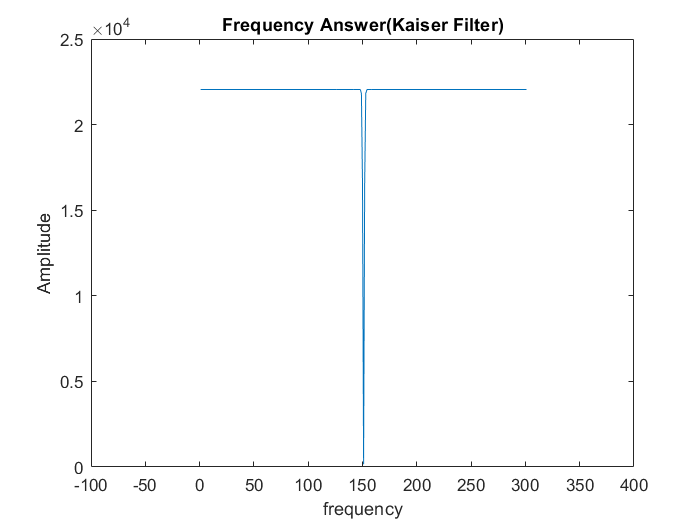

kaiserShift = circshift(kaiserVector,shiftSize);
kaiserFilterTimeDomain = shiftedHilbert .* transpose(kaiserShift);
kaiserFilterFrequencyDomain = fourierDiscreteStandardTransform(kaiserFilterTimeDomain);
w = (0:size(kaiserFilterFrequencyDomain,2)-1)*2*pi/(size(kaiserFilterFrequencyDomain,2)-1) - pi;
kaiserFilterFrequencyDomain = kaiserFilterFrequencyDomain.*exp(1i*-0.5*w);

figure
plot(abs(kaiserFilterFrequencyDomain));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency Answer(Kaiser Filter)');
xlim([-100 400])

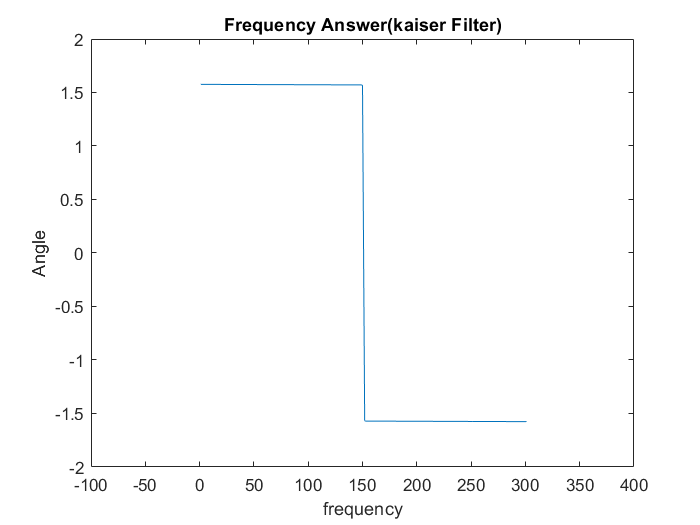

figure
plot(angle(kaiserFilterFrequencyDomain));
xlabel('frequency');
ylabel('Angle');
xlim([-100 400])
title('Frequency Answer(kaiser Filter)');

function out = dotDigitalWave(digitalWave,signals)
signalDotDigitalWave = digitalWave .* signals;
[numberOfSignals,eachSignalSize] = size(signals);
correlation = zeros(numberOfSignals,eachSignalSize);
for i = 1:numberOfSignals
    for j = 1:eachSignalSize
    correlation(i,j) = Correlation(signalDotDigitalWave(i,:),circshift(signalDotDigitalWave(i,:),j-1));
    end   
end
mean_correlation = mean(correlation,1);
out = mean_correlation;
end

function out = sdfViaCorrSignal(signal)
out = fftshift(fft(signal,size(signal,2)));
end

function [out,allSignals,correlation] = autocorrelation(length,frequency,sigma,T,numberOfSignals)
eachSignalSize = length*frequency;  % length & 
allSignals = zeros(numberOfSignals,eachSignalSize); % we can change it by fixing  the outputSize!
for i = 1:numberOfSignals
    allSignals(i,:) = digitalWave(length,frequency,sigma,T);
end
correlation = zeros(numberOfSignals,eachSignalSize);
for i = 1:numberOfSignals
    for j = 1:eachSignalSize
    correlation(i,j) = Correlation(allSignals(i,:),circshift(allSignals(i,:),j-1));
    end   
end
out = mean(correlation,1);
end

function out = digitalWave(length,frequencySampling,sigma,T)
Ddomain = rand * T;
zeroPartNumbers = floor(Ddomain*frequencySampling);
oneIntervalDomainSamples = floor(T*frequencySampling);
discreteDomain = floor(length*frequencySampling);
numberOfIntervals = floor((discreteDomain - zeroPartNumbers)/oneIntervalDomainSamples);
discreteOutputSignal = zeros(1,discreteDomain);
discreteOutputSignal(1,1:zeroPartNumbers) = 0; % during zero part it is zero.
startIndex = zeroPartNumbers + 1;
for i = 1:numberOfIntervals
    a_i = normrnd(0,sigma);
    if(i~=numberOfIntervals)
    discreteOutputSignal(1,startIndex:startIndex + oneIntervalDomainSamples) = a_i;
    startIndex = startIndex + oneIntervalDomainSamples + 1;
    else
    startIndex = startIndex + 1;
    discreteOutputSignal(1,startIndex:end) = a_i;
    end
end
out = discreteOutputSignal;
end

function output = Correlation(firstSignal,secondSignal)
output = sum(firstSignal.*conj(secondSignal));
end


function out = fourierDiscreteStandardTransform(signal)
out = fftshift(fft(signal,size(signal,2)));
end

function out = hamming(input,M,shift)
temp = 0.54-0.46*cos(2*pi*input/M);
out = circshift(temp,shift);
end

function [out,zeroIndex,domain] = hilbert(length,frequency)
domain = (-1)*length/2 + 1/(2*frequency) :1/frequency:length/2 + 1/(2*frequency);
signal = zeros(1,size(domain,2));
zeroInit = ceil(size(domain,2)/2);
signal(1:end) = 1./(pi*domain(1:end));
zeroIndex = zeroInit;
out = signal;
end

function [out,Tsignal] = sdf(signal)
Tsignal = fourierDiscreteStandardTransform(signal);
out = Tsignal.*conj(Tsignal);
end